# Virtual Environments Examples

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/3.0_Virtual_environments.html)

### Example 29 - Object space

Define house object

clear

Vhouse = [-0.5, 0.5, 0.5, -0.5, -0.5, 0.5, 0.5, -0.5, 0, 0 ;
          -1,  -1,   1,    1,   -1,  -1,   1,    1,  -1, 1 ;
           0,   0,   0,    0,    1,   1,   1,    1,   2, 2 ;
           1,   1,   1,    1,    1,   1,   1,    1,   1, 1];

Fhouse = [4, 3,  2,  1, 1 ;    % base
          1, 2,  6,  9, 5 ;    % front wall
          2, 3,  7,  6, 6 ;    % right wall
          3, 4,  8, 10, 7 ;    % back wall
          1, 5,  8,  4, 4 ;    % left wall
          6, 7, 10,  9, 9 ;    % right roof
          5, 9, 10,  8, 8 ];   % left roof

Plot object space

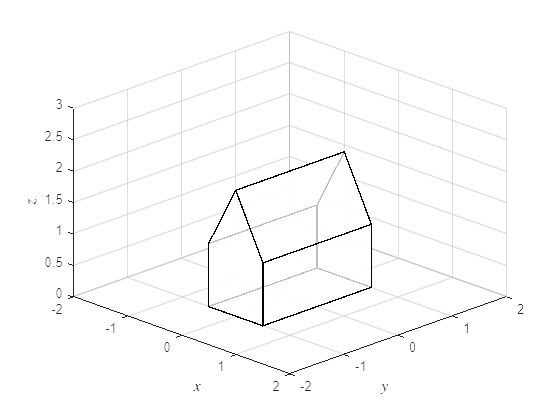

figure
patch("Vertices", Vhouse(1:3,:)', "Faces", Fhouse, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$y$", "Interpreter", "latex", "FontSize", 12)
zlabel("$z$", "Interpreter", "latex", "FontSize", 12)
view(45, 30)
axis([-2, 2, -2, 2, 0, 3])
grid on

### Example 30 - World space

Define cube object

Vcube = [ -1,  1,  1, -1, -1,  1, 1, -1 ;
          -1, -1,  1,  1, -1, -1, 1,  1 ;
          -1, -1, -1, -1,  1,  1, 1,  1 ;
           1,  1,  1,  1,  1,  1, 1,  1 ];

Fcube = [ 1, 4, 3, 2, 2 ;
          1, 2, 6, 5, 5 ; 
          2, 3, 7, 6, 6 ;
          3, 4, 8, 7, 7 ;
          4, 1, 5, 8, 8 ;
          5, 6, 7, 8, 8 ];

Define transformation parameters

theta = pi / 2;
c1 = [3, 3.5, 0];
c2 = [3, 1.5, 0];
c3 = [1.5, 1.5, 1.5];
s = [0.5, 0.5, 1.5];

Define transformation matrices

T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

S = @(s) [ s(1), 0,    0,    0 ;  
           0,    s(2), 0,    0 ; 
           0,    0,    s(3), 0 ; 
           0,    0,    0,    1 ];

Rz = @(theta) [ cos(theta), sin(theta), 0, 0 ;
               -sin(theta), cos(theta), 0, 0 ;
                0,           0,         1, 0 ;
                0,           0,         0, 1 ];

Add objects to world space

% Add first house object
Vobj = T(c1) * Rz(theta) * Vhouse;
Fobj = Fhouse;
V = Vobj;
F = Fobj;

% Add second house object
Vobj = T(c2) * Rz(theta) * Vhouse;
Fobj = Fhouse + size(V, 2);         % add number of vertices in world space to face array
V = [V, Vobj];
F = [F ; Fobj];

% Add tower object
Vobj = T(c3) * S(s) * Vcube;
Fobj = Fcube + size(V, 2);
V = [V, Vobj];
F = [F ; Fobj];

Plot world space

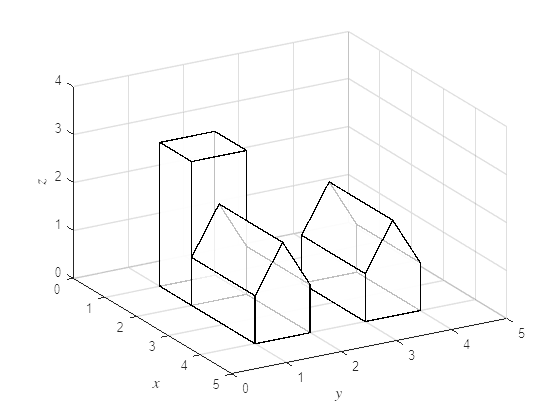

figure
patch("Vertices", V(1:3,:)', "Faces", F, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$y$", "Interpreter", "latex", "FontSize", 12)
zlabel("$z$", "Interpreter", "latex", "FontSize", 12)
view(60, 30)
axis([0, 5, 0, 5, 0, 4])
grid on

### Example 31 - Camera space

Define camera position and centre of view

p = [5 , 5 , 1.75];
c = [4 , 4 , 1.5];
k = [0 , 0 , 1];

Calculate alignment matrix

w = (p - c) / norm(p - c);
u = cross(k, w) / norm(cross(k, w));
v = cross(w, u);
A = [ u, -dot(p, u) ; 
      v, -dot(p, v) ;
      w, -dot(p, w) ;
      0, 0, 0, 1 ];

Align world space to the camera space

Vcamera = A * V;

Plot world space showing the camera position and axes

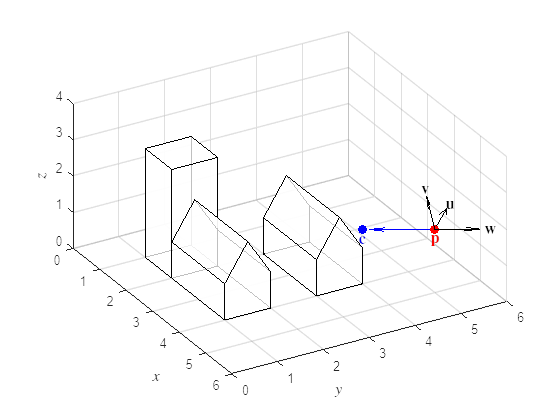

O = [p ; p ; p];
labels = ["$\mathbf{u}$", "$\mathbf{v}$", "$\mathbf{w}$"];

figure
patch("Vertices", V(1:3,:)', "Faces", F, FaceColor="w", FaceAlpha=0.75)
hold on
    quiver3(p(1), p(2), p(3), c(1)-p(1), c(2)-p(2), c(3)-p(3), "b", MaxHeadSize=1)
    quiver3(O(:,1), O(:,2), O(:,3), A(1:3,1), A(1:3,2), A(1:3,3), "k",  MaxHeadSize=1)
    plot3(p(1), p(2), p(3), "ro", MarkerFaceColor="r")
    plot3(c(1), c(2), c(3), "bo", MarkerFaceColor="b")
hold off
text(p(1), p(2), p(3)-0.25, "$\mathbf{p}$", FontSize=12, Interpreter="latex", HorizontalAlignment="center", Color="r")
text(c(1), c(2), c(3)-0.25, "$\mathbf{c}$", FontSize=12, Interpreter="latex", HorizontalAlignment="center", Color="b")
text(O(:,1)+1.1*A(1:3,1),O(:,2)+1.1*A(1:3,2),O(:,3)+1.1*A(1:3,3), labels, FontSize=12, Interpreter="latex", HorizontalAlignment="center")
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$y$", "Interpreter", "latex", "FontSize", 12)
zlabel("$z$", "Interpreter", "latex", "FontSize", 12)
view(60, 45)
axis([0, 6, 0, 6, 0, 4])
grid on

Plot camera space

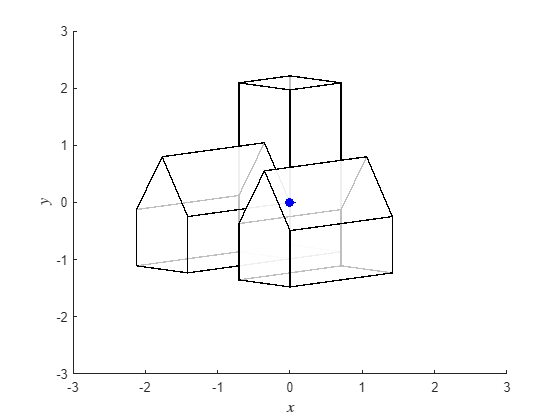

figure
h1 = axes;
patch("Vertices", Vcamera([1,3,2],:)', "Faces", F, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
hold on
plot3(0, 0, 0, "bo", MarkerFaceColor="b")
quiver3(0, 0, 0, 0, -1, 0, "b", MaxHeadSize=1)
hold off
set(h1, "Ydir", "reverse")
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$z$", "Interpreter", "latex", "FontSize", 12)
zlabel("$y$", "Interpreter", "latex", "FontSize", 12)
view(0,0)
axis([-3, 3, -6, 0, -3, 3])

### Exercise 32 - Screen space

Define projection parameters

near = 1;
far = 5;
fov = pi/2;
aspect = 4/3;

Calculate projection matrix

r = near * tan(fov / 2);
t = r / aspect;
P = [-near / r, 0, 0, 0 ;
     0, -near / t, 0, 0 ;
     0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
     0, 0, 1, 0 ];

Calculate screen space co-ordinates

Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

Plot camera space with viewing frustum

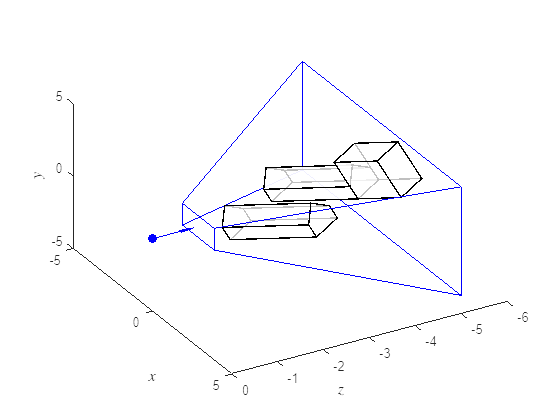

rfar = far * tan(fov / 2);
tfar = rfar / aspect;
Vfrustum = [ -r,     r,     rfar, -rfar, -r,     r,     rfar, -rfar ;
             -t,    -t,    -tfar, -tfar,  t,     t,     tfar,  tfar ;
             -near, -near, -far,  -far,  -near, -near, -far,  -far  ;
              1,     1,     1,     1,     1,     1,     1,     1    ];

figure()
h1 = axes;
patch("Vertices", Vcamera([1,3,2],:)', "Faces", F, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
patch("Vertices", Vfrustum([1,3,2],:)', "Faces", Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0,0,0,"bo",MarkerFaceColor="b")
quiver3(0,0,0,0,-1,0, "b", MaxHeadSize=1)
hold off
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$z$", "Interpreter", "latex", "FontSize", 12)
zlabel("$y$", "Interpreter", "latex", "FontSize", 12)
set(h1, "Ydir", "reverse")
view(60,45)
axis([-5, 5, -6, 0, -5, 5])

Plot screen space

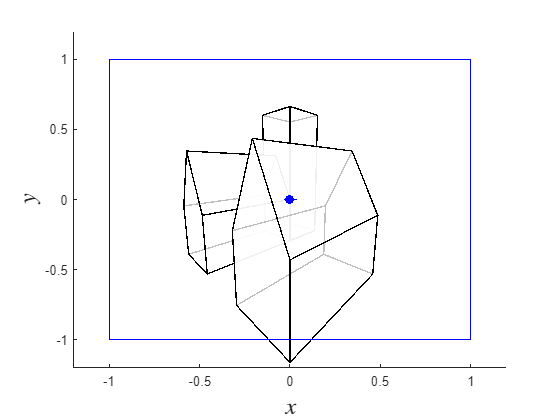

Vfrustum = P * Vfrustum;
Vfrustum = Vfrustum ./ Vfrustum(4,:);

% Plot screen space viewed from the side
figure()
h1 = axes;
patch("Vertices", Vscreen([1,3,2],:)', "Faces", F, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
patch("Vertices", Vfrustum(1:3,:)', "Faces", Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0, 1, 0,"bo",MarkerFaceColor="b")
quiver3(0, 1, 0, 0, -0.5, 0, "b", MaxHeadSize=1)
hold off
xlabel("$x$", "Interpreter", "latex", "FontSize", 18)
ylabel("$z$", "Interpreter", "latex", "FontSize", 18)
zlabel("$y$", "Interpreter", "latex", "FontSize", 18)
set(h1, "Ydir", "reverse")
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])